addpath functions\
addpath rawData\
latex_interpreter
systemName = 'ieee123';
numAreas = '4';
Area = 2;
systemDataFolder = strcat("rawData/", systemName, "/numAreas_", num2str(numAreas), "/");

filenameBusData_Area = strcat(systemDataFolder, "area", num2str(Area), '/powerdataActualBusNums.csv');
busData_Area = readmatrix(filenameBusData_Area);
busDataTable_Area = array2table(busData_Area, 'VariableNames', {'bus', 'P_L', 'Q_L', 'Q_C', 'P_der', 'busType'});

N_Area = size(busData_Area, 1);     % total number of nodes

filenameBranchData_Area = strcat(systemDataFolder, "area", num2str(Area), '/linedataActualBusNums.csv');
branchData_Area = readmatrix(filenameBranchData_Area);
branchDataTable_Area = array2table(branchData_Area, 'VariableNames', {'fb', 'tb', 'R', 'X'});

pairs = branchData_Area(:, 1:2)

pairs =     15   117
   117    54
    54    55
    55    56
    56    57
    56    59
    57    58
    59    60
    59    62
    60    61



% Find the number of unique nodes in the pair array
nodes = unique(pairs)

nodes =     15
    54
    55
    56
    57
    58
    59
    60
    61
    62



% Create a mapping from original node number to new node number
mapping = zeros(max(nodes), 1);
mapping(nodes) = 1:length(nodes)

mapping =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% Convert pairs to new node numbers
new_pairs = mapping(pairs)

new_pairs =      1    17
    17     2
     2     3
     3     4
     4     5
     4     7
     5     6
     7     8
     7    10
     8     9


% Create an adjacency matrix from the new pairs
spr_matrix = sparse([new_pairs(:, 1), new_pairs(:, 2)], [new_pairs(:, 2), new_pairs(:, 1)], 1, N_Area, N_Area)

spr_matrix =   (17,1)        1
   (3,2)        1
  (17,2)        1
   (2,3)        1
   (4,3)        1
   (3,4)        1
   (5,4)        1
   (7,4)        1
   (4,5)        1
   (6,5)        1
   (5,6)        1
   (4,7)        1
   (8,7)        1
  (10,7)        1
   (7,8)        1
   (9,8)        1
   (8,9)        1
   (7,10)       1
  (11,10)       1
  (12,10)       1
  (19,10)       1
  (10,11)       1
  (18,11)       1
  (10,12)       1
  (13,12)       1
  (12,13)       1
  (14,13)       1
  (13,14)       1
  (15,14)       1
  (14,15)       1
  (16,15)       1
  (15,16)       1
   (1,17)       1
   (2,17)       1
  (11,18)       1
  (10,19)       1


adj_matrix = full(spr_matrix)

adj_matrix =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0 


% Plot the graph
G_Area = graph(adj_matrix);
T_Area = dfsearch(G_Area, 1, 'edgetonew')

T_Area =      1    17
    17     2
     2     3
     3     4
     4     5
     5     6
     4     7
     7     8
     8     9
     7    10


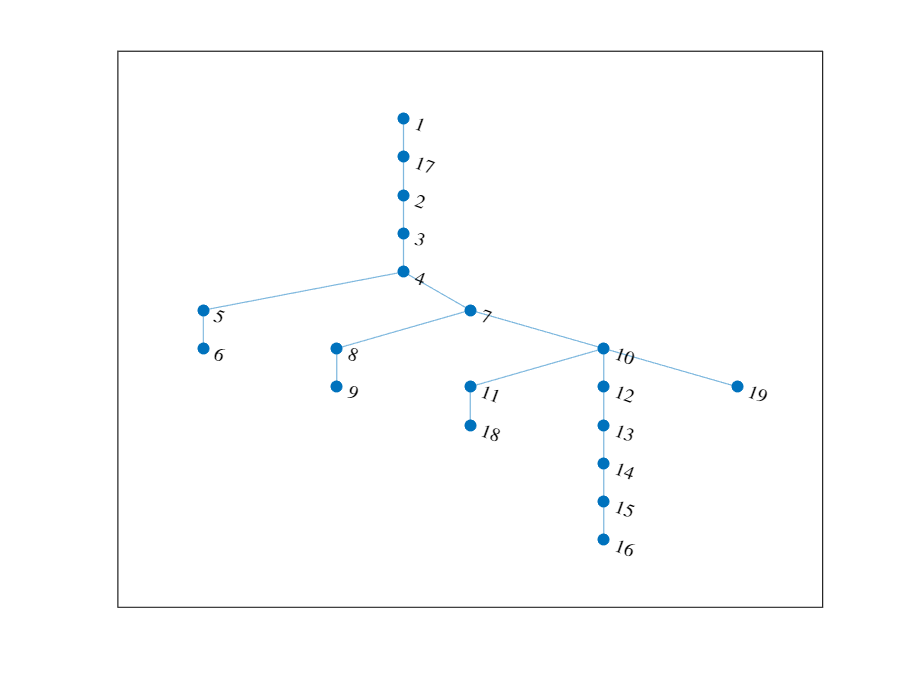

plot(G_Area);